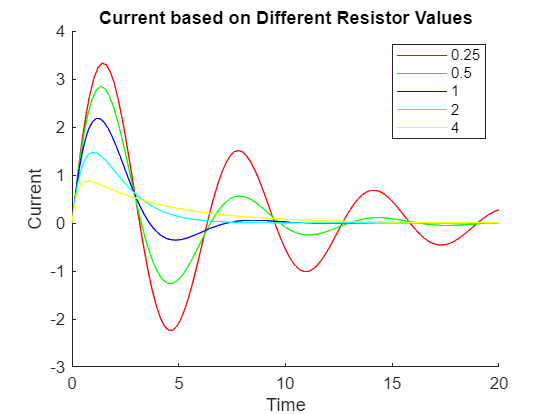

L = 1;
C = 1;
I0 = 0;            
dIdt0 = 4;
tspan = [0 20];

y0 = [I0, dIdt0];

% dI/dt = v1
% d^2I/dt^2 = (-R/L) * v1 - (1/(L*C)) * I

R025 = 0.25;
odefun025 = @(t, y) [y(2); (-R025/L)*y(2) - (1/(L*C))*y(1)];

R05 = 0.5;
odefun05 = @(t, y) [y(2); (-R05/L)*y(2) - (1/(L*C))*y(1)];

R1 = 1;
odefun1 = @(t, y) [y(2); (-R1/L)*y(2) - (1/(L*C))*y(1)];

R2 = 2;
odefun2 = @(t, y) [y(2); (-R2/L)*y(2) - (1/(L*C))*y(1)];

R4 = 4;
odefun4 = @(t, y) [y(2); (-R4/L)*y(2) - (1/(L*C))*y(1)];

[x025, y025] = ode45(odefun025, tspan, y0);
[x05, y05] = ode45(odefun05, tspan, y0);
[x1, y1] = ode45(odefun1, tspan, y0);
[x2, y2] = ode45(odefun2, tspan, y0);
[x4, y4] = ode45(odefun4, tspan, y0);

figure;
hold on;
title('Current based on Different Resistor Values');
xlabel('Time');
ylabel('Current');

plot(x025, y025(:,1), 'r', 'DisplayName', '0.25');
plot(x05, y05(:,1), 'g', 'DisplayName', '0.5');
plot(x1, y1(:,1), 'b', 'DisplayName', '1');
plot(x2, y2(:,1), 'c', 'DisplayName', '2');
plot(x4, y4(:,1), 'y', 'DisplayName', '4');

legend;
hold off;